# EE110B Lab 2

# Name: Buddy Ugwumba SID: 862063029

## 1) Use MATLAb to generate a random sequence $x\left\lbrack n\right\rbrack$ for $n=0,1,\;\ldotp \ldotp \ldotp \;,\;99\ldotp$ Also set $x\left\lbrack n\right\rbrack =0$ for $n<0$ and $n>99$

The main idea is as such: To find the output of any arbitrary discrete time signal $x\left\lbrack n\right\rbrack$ we perform the convolutgion of that arbitray signal and its impulse response $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$. It's impulse response $h\left\lbrack n\right\rbrack$ is found by making the input of the arbitrary system the delta function $x\left\lbrack n\right\rbrack =\;\delta \left\lbrack n\right\rbrack$ where $\delta \left\lbrack n\right\rbrack =\left\lbrack \begin{array}{cc}
0 & n\not= 0\\
1 & n=0
\end{array}\right\rbrack$

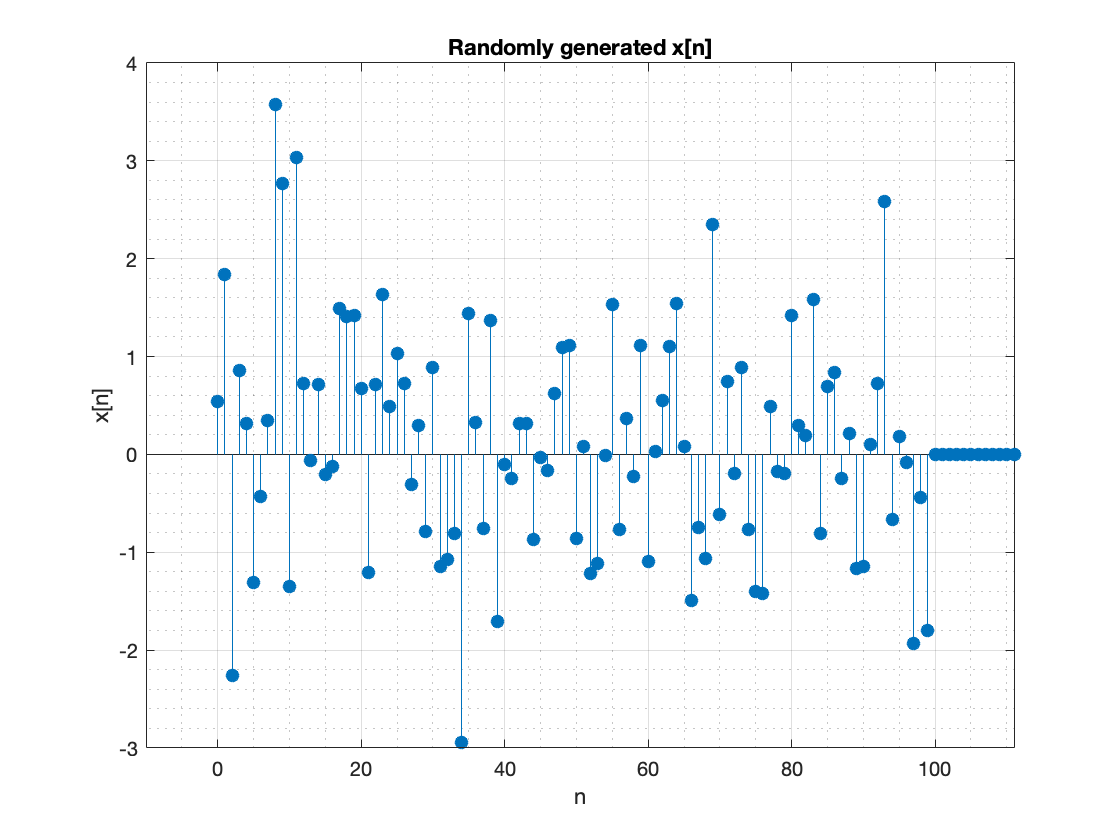

% Random seed, allows how to set a random seed for a random sequence. This
% means that we're always using the random seed of 0. This means that if I
% run the code multiple times I will get the same results. If you want
% different sequences comment this out
rng(0);
% Generates a sample (random sequence) from Gaussian distribution 
x = randn(1,500);
n = 0:1:500;
% The code below makes its so that when we plot the randomly generated
% sequence in line 7, against n, the values for n > 99 and n < 0 are equal
% to 0
x(n>99) = 0;
x(n<0) = 0;
figure
stem(n, x, 'filled');
xlim([-10, 111]);
xlabel('n');
ylabel('x[n]');
title('Randomly generated x[n]')
grid on 
grid minor

###     a) Consider a discrete time LTI system with the impulse response 

### 
$$h\left\lbrack n\right\rbrack =0\ldotp 9^{n-1} \left\lbrace u\left\lbrack n-1\right\rbrack -u\left\lbrack n-99\right\rbrack \right\rbrace$$


### Compare and plot the output $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$ for $n=0,1,\ldotp \ldotp \ldotp ,100$

The above equation can be simplified to the following 

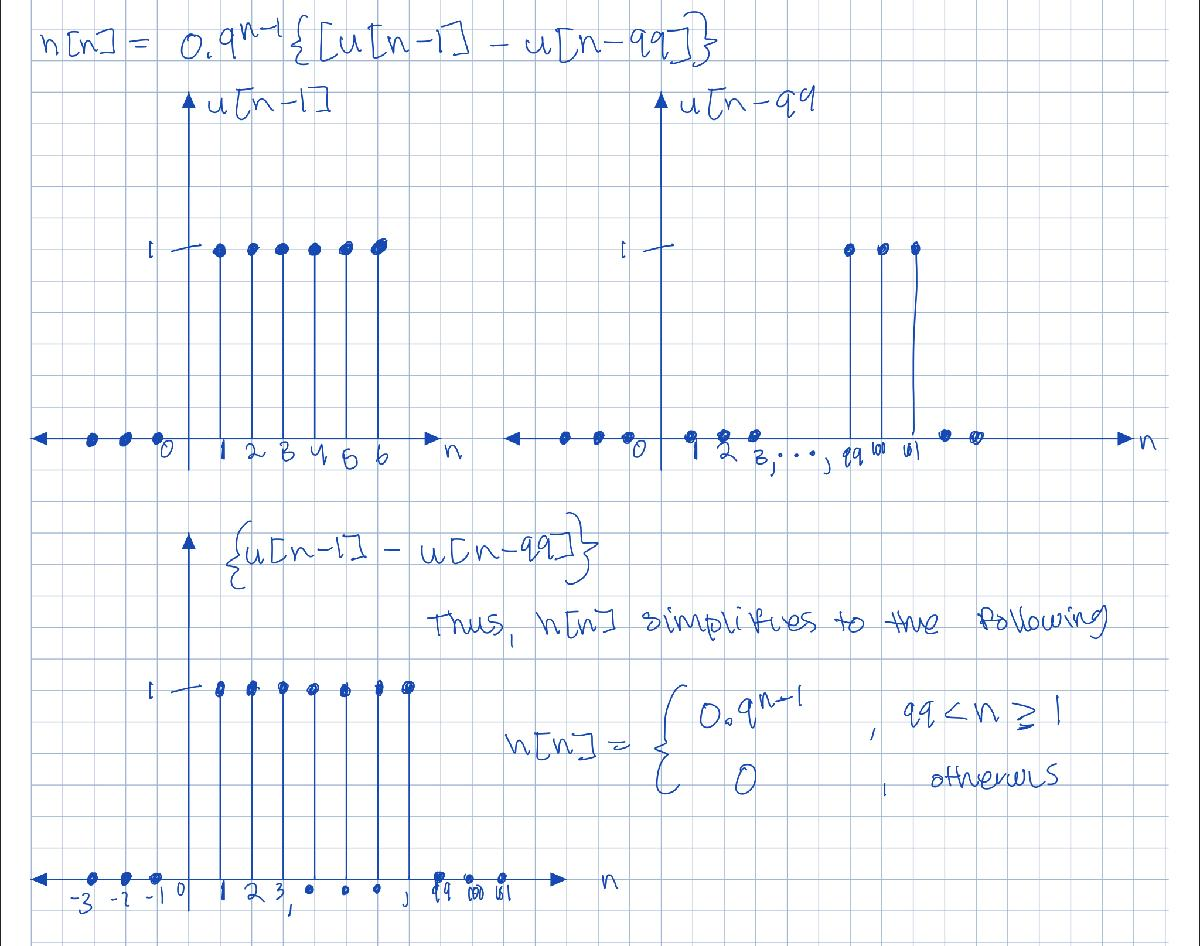

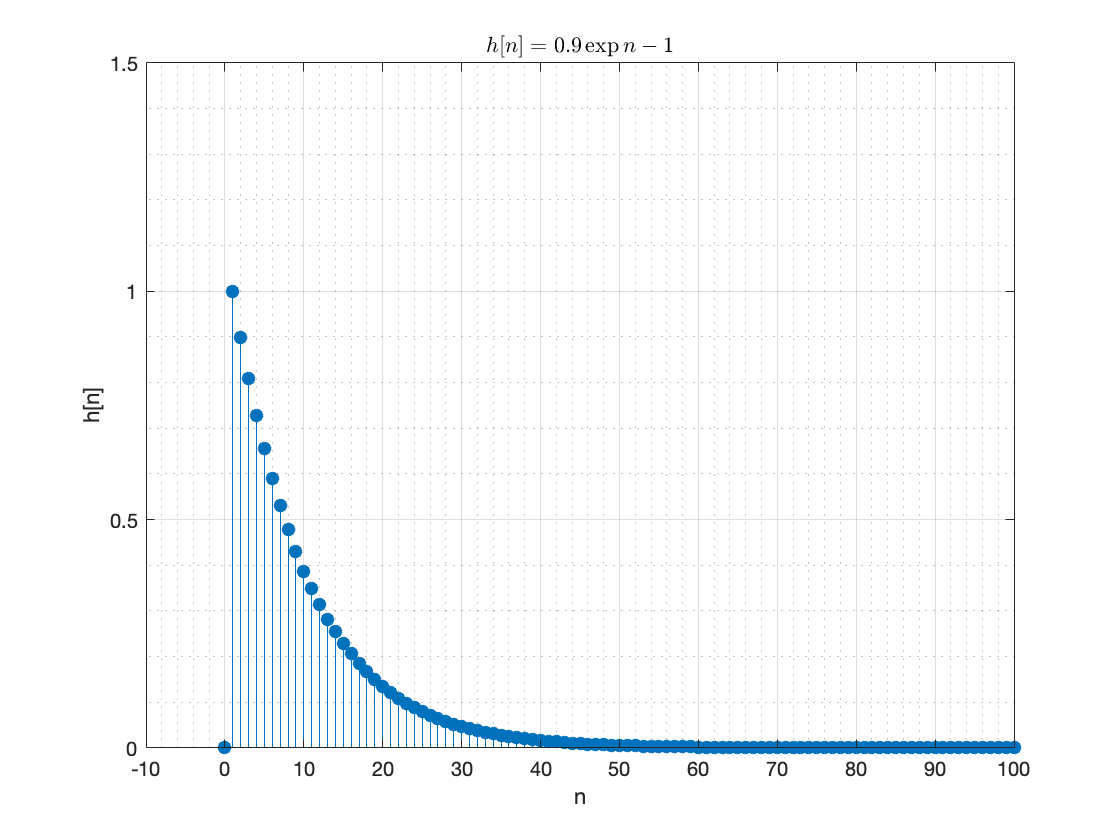

h_n = 0.9.^(n-1);
h_n(n<1) = 0;
h_n(n>98) = 0;
figure
stem(n, h_n, 'filled');
ylim([0,1.5]);
xlim([-10, 100]);
xlabel('n');
ylabel('h[n]')
title('$$h[n] = 0.9\exp{n-1}$$', 'Interpreter','latex');
grid on
grid minor

### Compute and plot the output $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$ for $n=0,1,\ldotp \ldotp \ldotp ,100\ldotp$ 

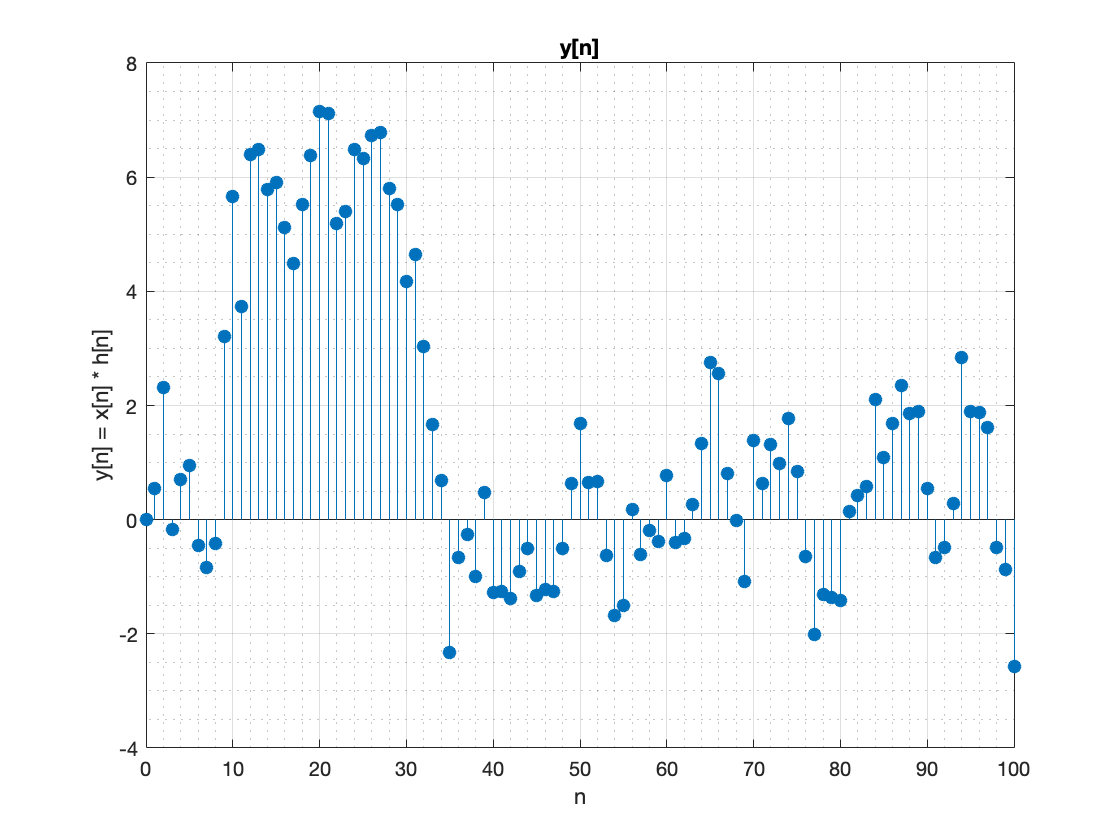

% In order to perform the convolution use the conv() 
y_n = conv(x,h_n);
figure
stem(n(1:101), y_n(1:101), 'filled')
xlabel('n');
title('y[n]');
ylabel('y[n] = x[n] * h[n]');
grid on
grid minor

### b) Consider another discretec-time LTI system governed by the recursive difference equation:

### 
$$y\left\lbrack n+1\right\rbrack =0\ldotp 9y\left\lbrack n\right\rbrack +x\left\lbrack n\right\rbrack$$


### where $y\left\lbrack -1\right\rbrack =0$. Use the recursive equation to compute and then plot $y\left\lbrack n\right\rbrack$ for $n=0,1,\ldotp \ldotp \ldotp ,100$.

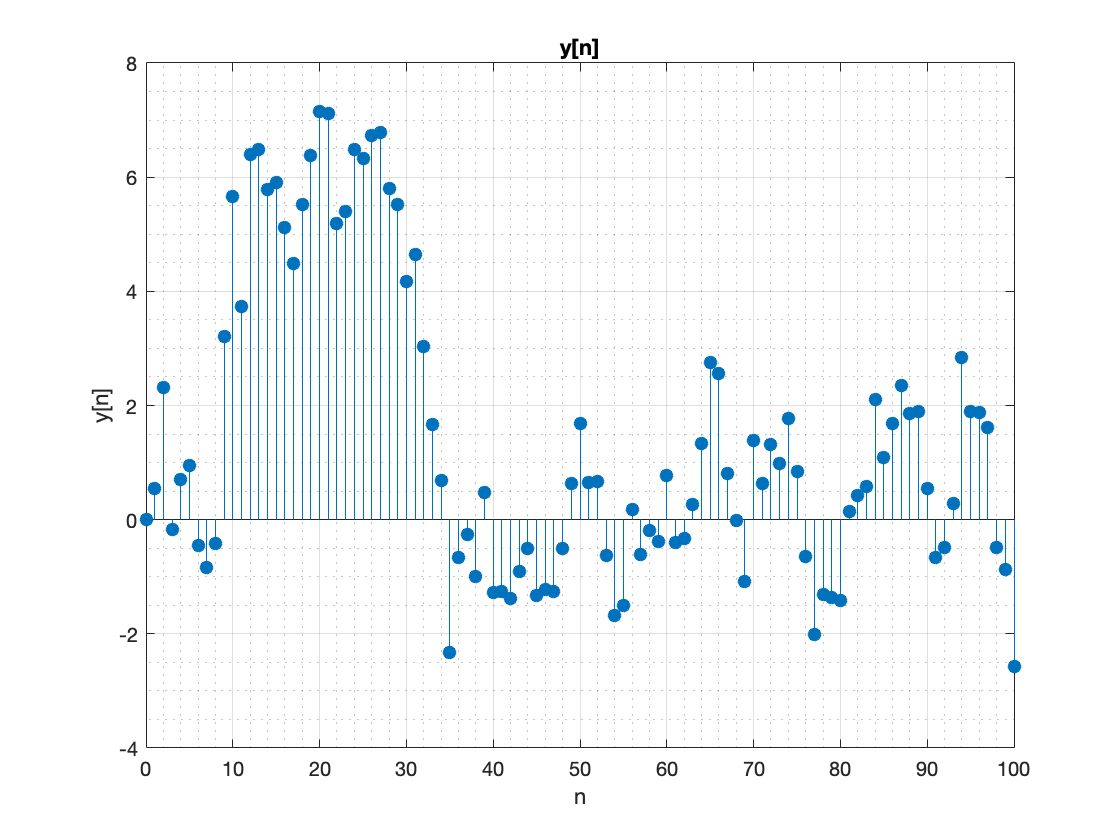

% y(0) = 0.9y(-1) + x(-1)
%y(0) = 0 because values for x less than 1 are 0
% creates a zero vector 
y =  zeros(1,101);
y(1) = 0;
% run the recursion
for k = 1:100
    y(k+1) = 0.9*y(k) + x(k);
end
figure
stem(n(1:101), y, 'filled');
xlabel('n');
ylabel('y[n]');
title('y[n]');
grid on
grid minor

### C) Compare the above results. Are they close to each other? Why?

The above results are close to each other. For example, $x\left\lbrack n\right\rbrack =35$ produces $y\left\lbrack n\right\rbrack =-2\ldotp 327$ for both graphs. These results are the same because the convolution is similar to the difference equation. In the difference equation. Both are L.T.I systems meaning that both have an impulse response. The impulse responser is unqiue to each arbitrary signal. Since we are using the same arbitarary singal the output should be the same. 

## 2) Use MATLAB to generate another random sequence $x\left\lbrack n\right\rbrack \;$for $n=0,1,\ldotp \ldotp \ldotp ,99$. Also set $x\left\lbrack n\right\rbrack =0$ for $n<0$ and $n>99$.

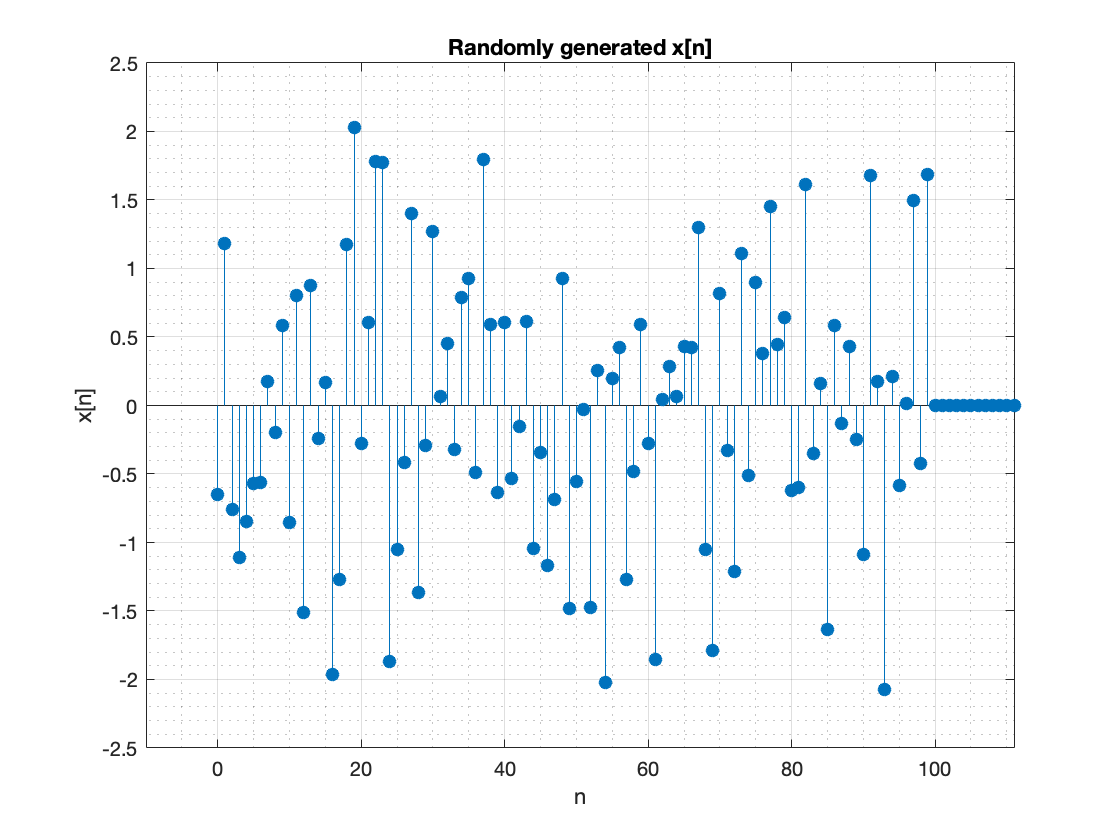

rng(1);
x_2 = randn(1,500);
n_2 = 0:1:500;
% The code below makes its so that when we plot the randomly generated
% sequence in line 7, against n, the values for n > 99 and n < 0 are equal
% to 0
x_2(n_2>99) = 0;
x_2(n_2<0) = 0;
figure
stem(n_2, x_2, 'filled');
xlim([-10, 111]);
xlabel('n');
ylabel('x[n]');
title('Randomly generated x[n]')
grid on 
grid minor

###     a) Consider a discrete time LTI system with the impulse response 

### 
$$h\left\lbrack n\right\rbrack =0\ldotp 9^{n-1} \mathrm{cos}\left(\frac{\pi }{5}\left(n-1\right)\right)\left\lbrace u\left\lbrack n-1\right\rbrack -u\left\lbrack n-100\right\rbrack \right\rbrace$$


The above equation can be simplified to the following 

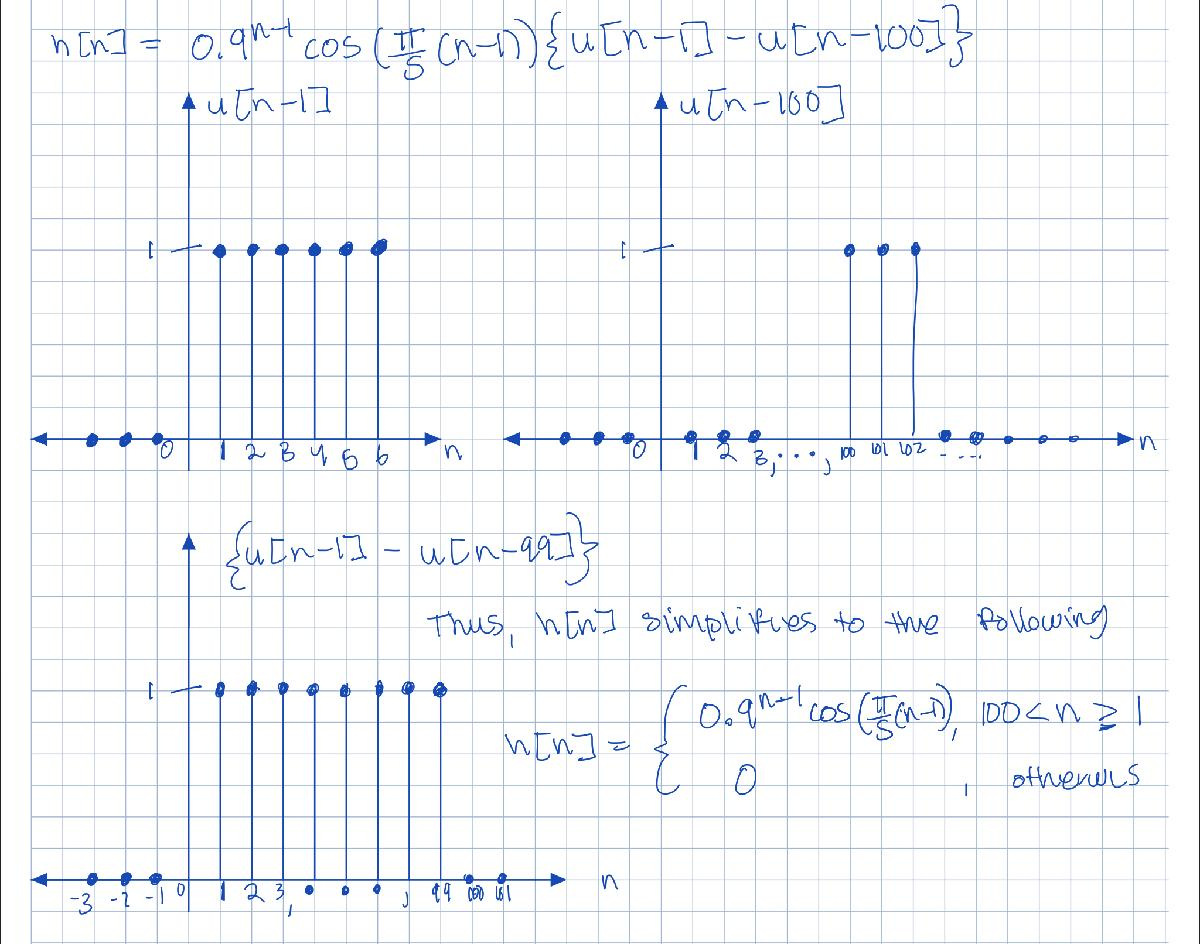

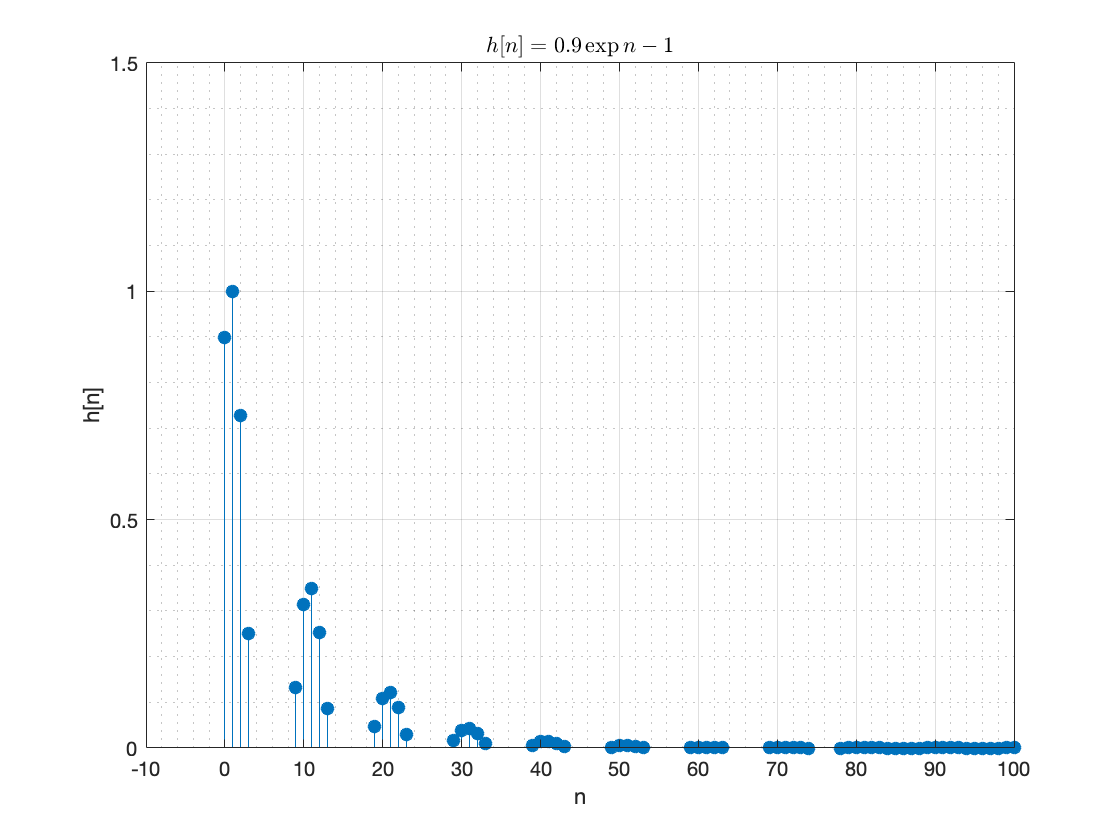

h_n_2 = 0.9.^(n-1).*cos((pi/5)*(n-1));
h_n(n<1) = 0;
h_n(n>99) = 0;
figure
stem(n, h_n_2, 'filled');
ylim([0,1.5]);
xlim([-10, 100]);
xlabel('n');
ylabel('h[n]')
title('$$h[n] = 0.9\exp{n-1}$$', 'Interpreter','latex');
grid on
grid minor

### Compare and plot the output $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack *h\left\lbrack n\right\rbrack$ for $n=0,1,\ldotp \ldotp \ldotp ,100$

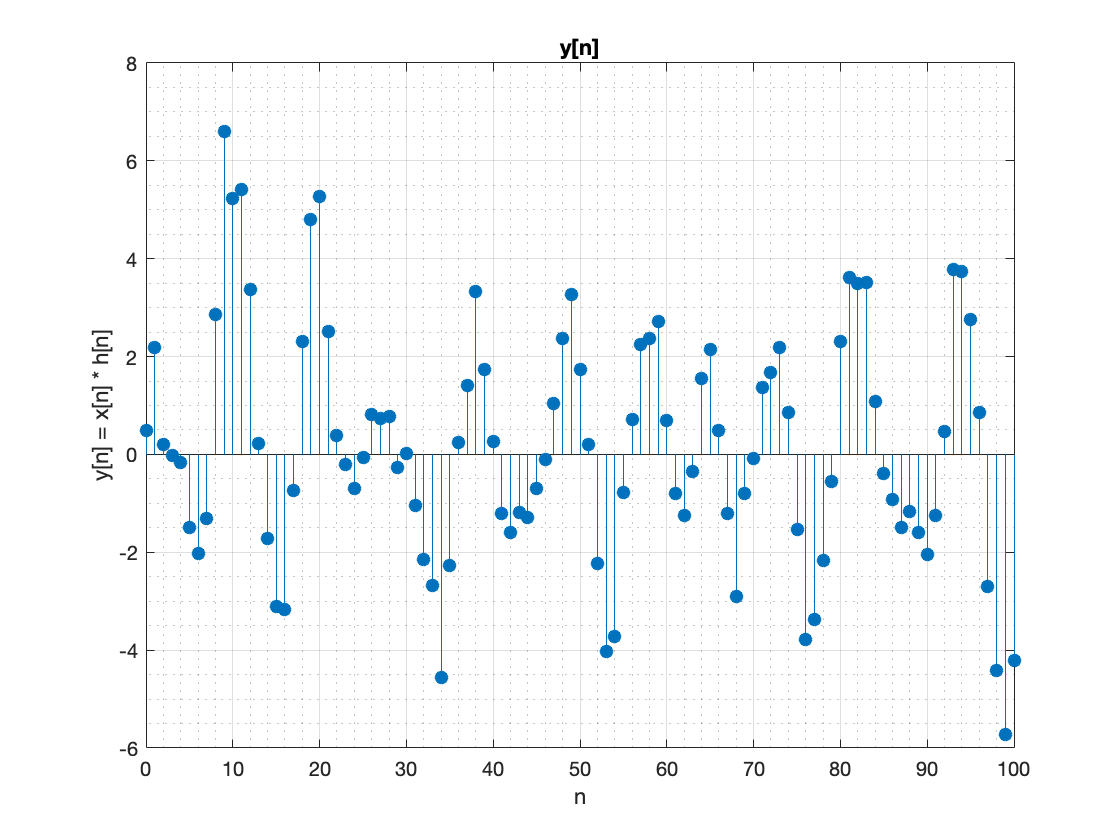

% In order to perform the convolution use the conv() 
y_n = conv(x,h_n_2);
figure
stem(n_2(1:101), y_n(1:101), 'filled')
xlabel('n');
title('y[n]');
ylabel('y[n] = x[n] * h[n]');
grid on
grid minor

### b) Consider another discretec-time LTI system governed by the recursive difference equation:

### 
$$y\left\lbrack n+2\right\rbrack =1\ldotp 8\mathrm{cos}\left(\frac{\pi }{5}\right)y\left\lbrack n+1\right\rbrack \;-\;0\ldotp 81y\left\lbrack n\right\rbrack +x\left\lbrack n+1\right\rbrack -0\ldotp 9\mathrm{cos}\left(\frac{\pi }{5}\right)x\left\lbrack n\right\rbrack$$


### and the initial condition $y\left\lbrack -1\right\rbrack =\;y\left\lbrack -2\right\rbrack \;=0$. Compae and plot the outuput $y\left\lbrack n\right\rbrack$ for $n=0,1,\ldotp \ldotp \ldotp ,100$ using the recursive equation

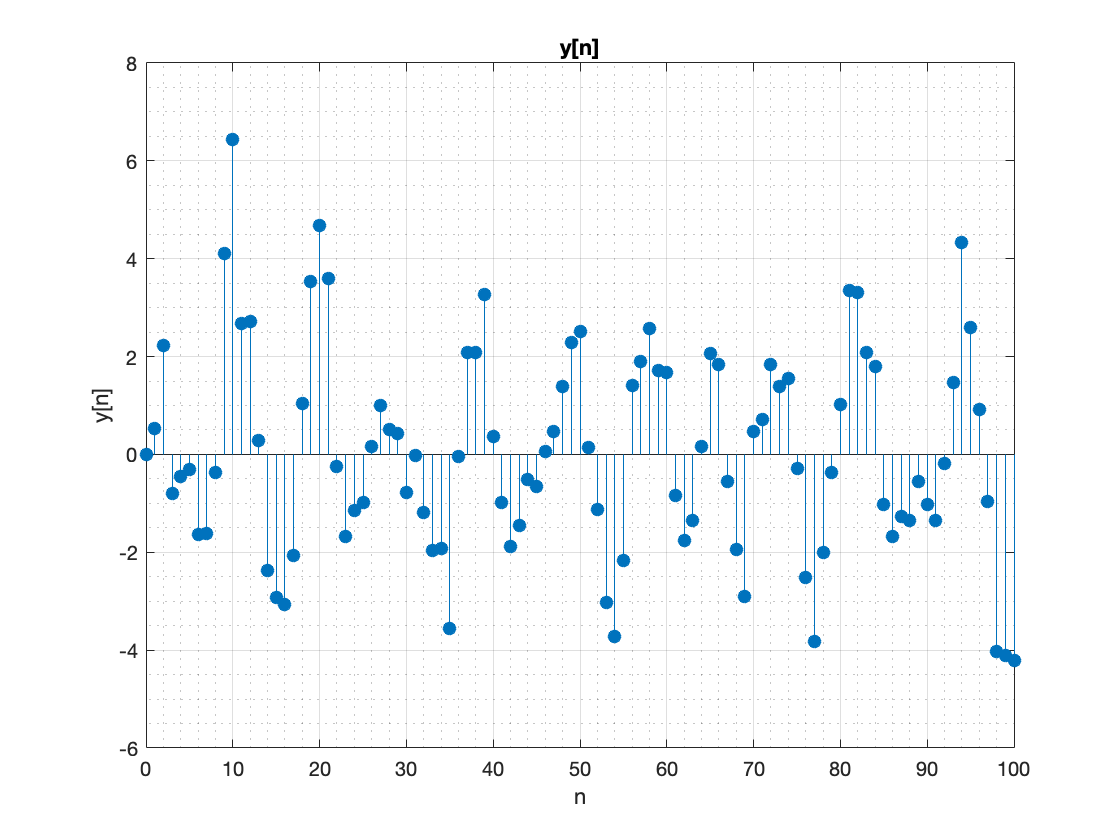

% y(0) = 1.8*cos(pi/5)y(-1) + 0.81y(-2) + x(-1) - 0.9cos(pi/5)x(-2)
% y(0) = 0 because values for x less than 1 are 0
% y(1) = x(1)
% creates a zero vector 
y =  zeros(1,101);
y(1) = 0;
y(2) = x(1);
% run the recursion
for k = 1:99
    y(k+2) = 1.8*cos(pi/5)*y(k+1) - 0.81*y(k) + x(k+1) - 0.9*cos(pi/5)*x(k);
end
figure
stem(n_2(1:101), y, 'filled');
xlabel('n');
ylabel('y[n]');
title('y[n]');
grid on
grid minor

### C) Compare the above two results. Are they close to each other?

the above results are close biut not exact. the convolution provides results that are shifted further to the left than the results obtained via the difrference equation. 